Question 1

t = -10:0.01:10;
a = t>0;
b = 3*((t-1)>0);
c = (1-t)>0;
d = a + sin(t);
k = a .* sin (t);
f = t.*a;
l = (5-t).*((5-t)>0);
m = dirac(t-2);
idx = m == Inf;
m(idx) = 1;

Question 2

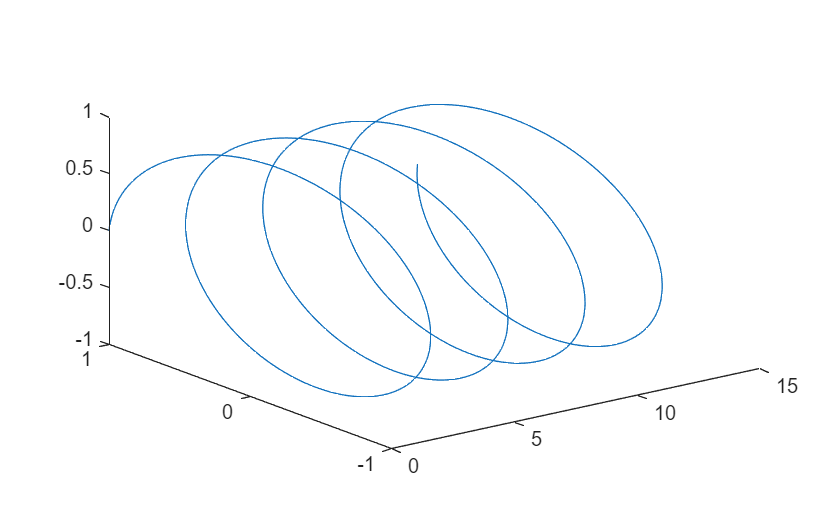

x = linspace(0, 4*pi, 500);
w = 2;
func = exp(j*x*w);
plot3(x,real(func), imag(func))

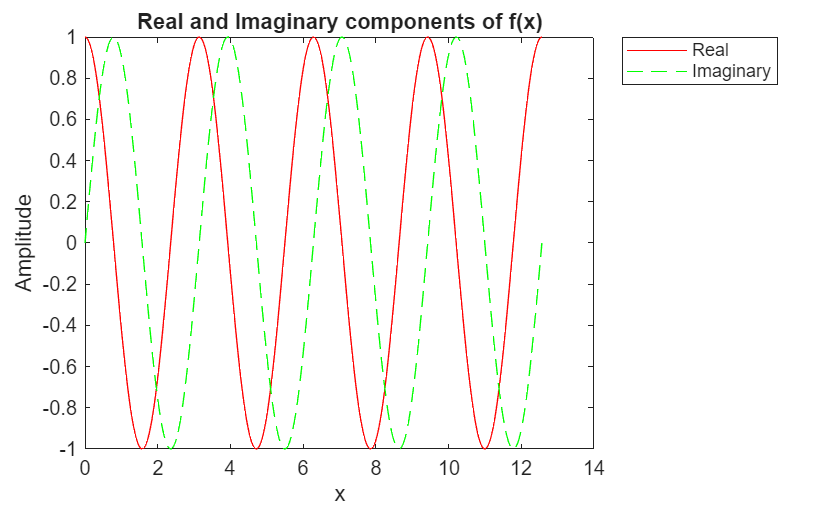

plot(x,real(func), 'r-');
hold on
plot(x, imag(func), 'g--')
hold off 
title("Real and Imaginary components of f(x)")
xlabel('x');
ylabel('Amplitude');
legend("Real", "Imaginary")

Question 3:

t = -5:0.01:5;
x1 = (t>0);
x2 = 2*((t-1)>0);
a3 = 3;
b3 = -1;
T = @(tt,x) tt.*(x.^2);
LHS = T(t, a3*x1 + b3*x2);
RHS = a3*T(t, x1) + b3*T(t, x2);
difference = norm(LHS - RHS);
threshold = 1e-6;
if difference < threshold
    Q3 = 1;
else
    Q3 = 0;
end


Question 4:

t = -10:10;
u = @(tt) (tt > 0);
u1 = double(u(t))

u1 =      0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1


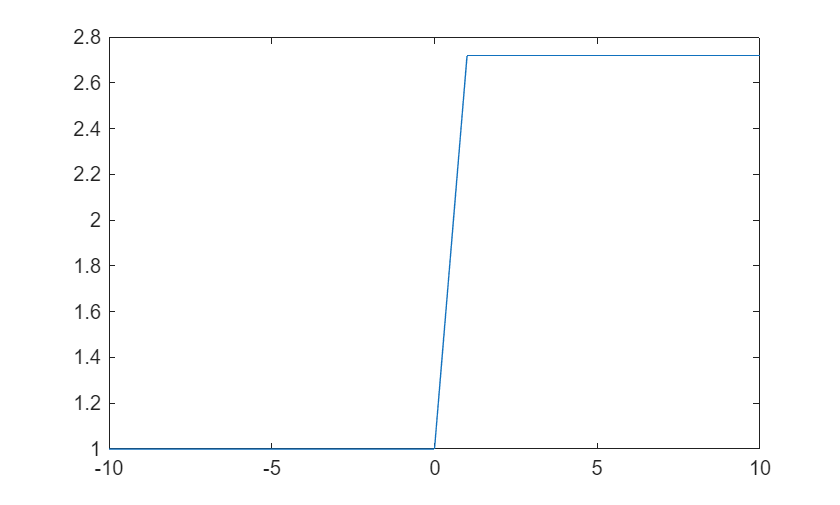

V1 = exp(u1);
plot(t,V1)

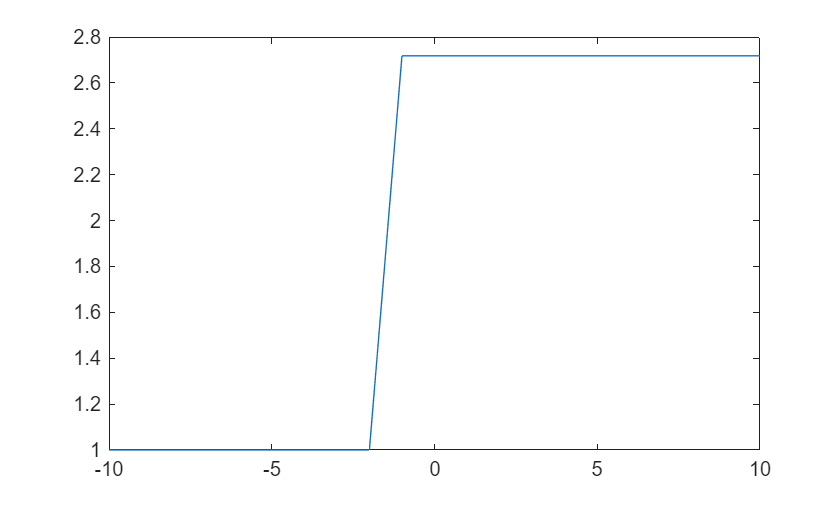

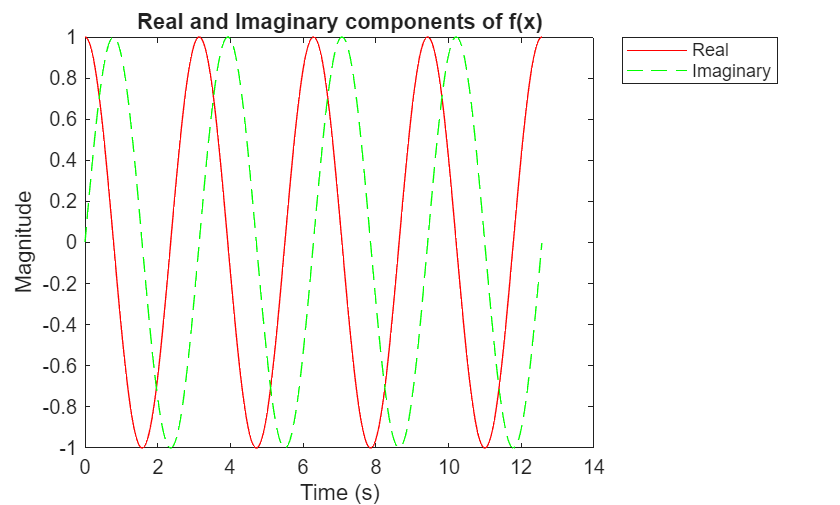

V2 = exp(double(u(t+2)));
plot(t, V2)